依赖[统一实验分析作图v18.0.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

DataSet=TransferLearning.FullCalcium;

光声迁移

LACalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig1G'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

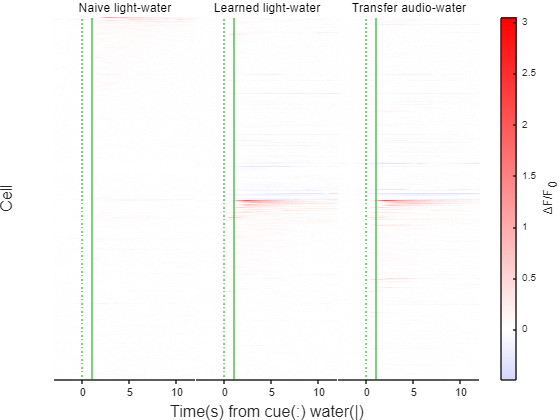

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(LACalcium,["Naive_light_water","Learned_light_water"]).NTATS{:,:,["Naive_light_water","Learned_light_water","Transfer_audio_water"]},["Naive light-water","Learned light-water","Transfer audio-water"],Colors,false);

NumMice=numel(unique(DataSet.Cells.Mouse(ismember(DataSet.Cells.CellUID,LACalcium.CellUID))))

NumMice = 17

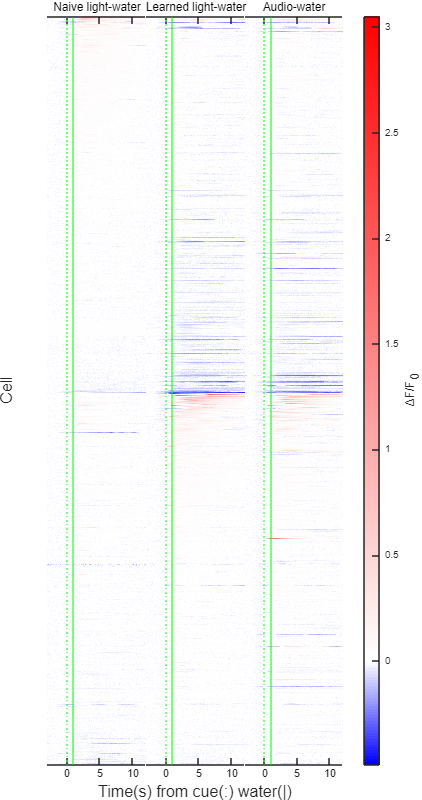

MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('Fig1G.svg'),'-dsvg');

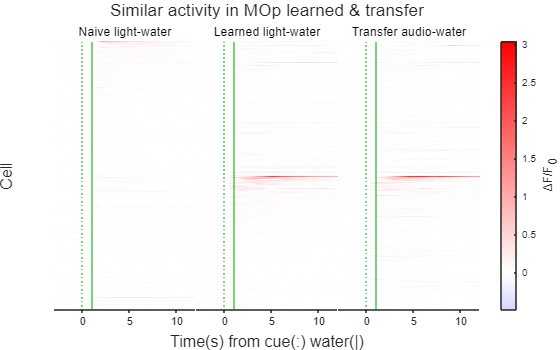

title(Layout,'Similar activity in MOp learned & transfer');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig1G.PPT.svg'),'-dsvg');

声光迁移

ALCalcium=DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'声光迁移'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1])

Colors =     1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000
    0.0000    1.0000    0.0000


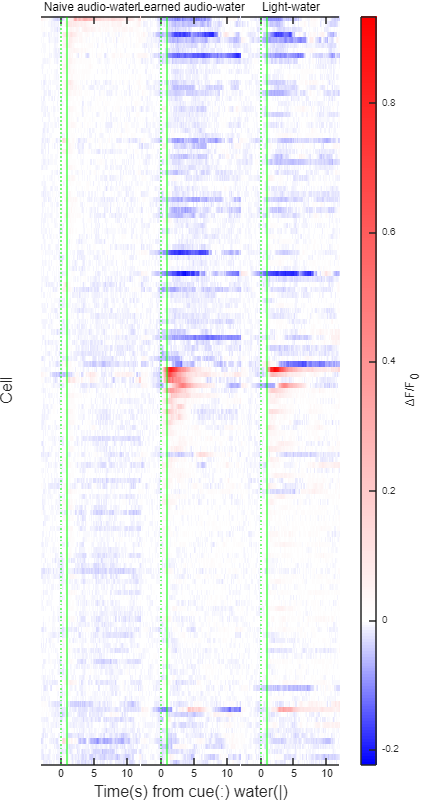

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(ALCalcium,["Naive_task_A","Learned_task_A"]).NTATS{:,:,["Naive_task_A","Learned_task_A","Task_B"]},["Naive audio-water","Learned audio-water","Light-water"],Colors([2,1,3],:),false);
MATLAB.Graphics.FigureAspectRatio(1,2,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('FigS1G.svg'),'-dsvg');

声光迁移RSPd

QueryTable=UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'声光迁移RSPd');
RSPdCalcium=DataSet.QueryNTATS(QueryTable,UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median);

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
QueryTable.GroupName(:)="All";

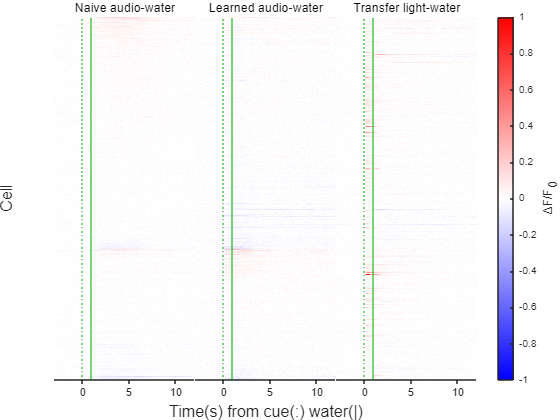

Layout=TransferLearning.BasicHeatmap(UniExp.HeatmapSort(RSPdCalcium,["Naive_task_A","Learned_task_A"]).NTATS{:,:,["Naive_task_A","Learned_task_A","Task_B"]},["Naive audio-water","Learned audio-water","Transfer light-water"],Colors,false,CLim=[-1,1]);

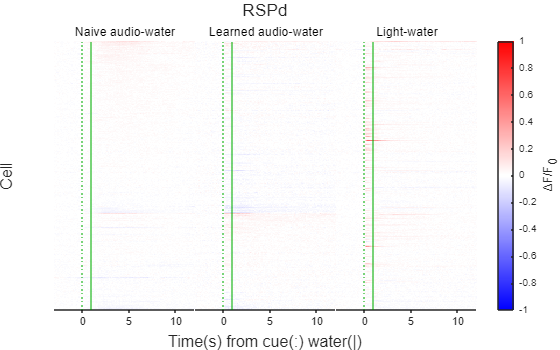

title(Layout,'RSPd');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Amplify);
print(TransferLearning.ProjectPath('RSPdTransfer.svg'),'-dsvg');

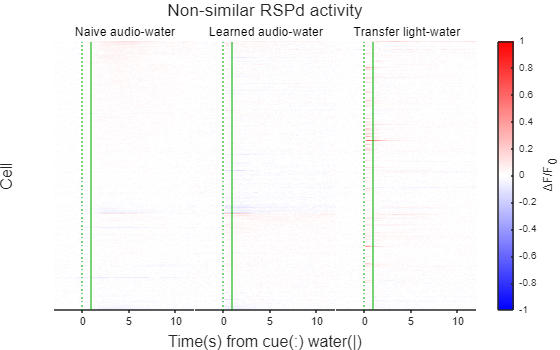

title(Layout,'Non-similar RSPd activity');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('RSPdTransfer.PPT.svg'),'-dsvg');

NumMice=numel(unique(DataSet.TableQuery("Mouse",QueryTable).All.Mouse))

NumMice = 4